filename = 'carbon_emissions_data.mat';
load(filename)

time = carbon_emissions_data(:,1); % Date/time in years. (column 1)
carbon = carbon_emissions_data(:,2); % carbon emissions data (column 2)
fig1 = figure()

fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties



emissions=plot(time,carbon,'-b','LineWidth',3)

emissions =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×263 double]
              YData: [1×263 double]
              ZData: [1×0 double]

  Show all properties


title('Global Carbon Emissions in Million Metric Tons of Carbon')
xlabel('Year')
ylabel('Carbon Emissions')
hold on
shift = mean(time) % exact mean of the data is 1883

shift = 1883

D = [ones(size(time)) (time - shift)]; % we expand about the midyear of the data
D2 = transpose(D) * D

D2 =          263           0
           0     1515932


y=carbon;

b=inv(D2)*transpose(D)*y

b = 	1.0e+03 *

    1.5288
    0.0255


y1 = @ (t) b(1) + b(2) * (t - shift);
y_est = D*b;
best_line = plot([1750, 2050], y1([1750, 2050]), 'r', 'LineWidth', 3)

best_line =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1750 2050]
              YData: [-1.8625e+03 5.7869e+03]
              ZData: [1×0 double]

  Show all properties


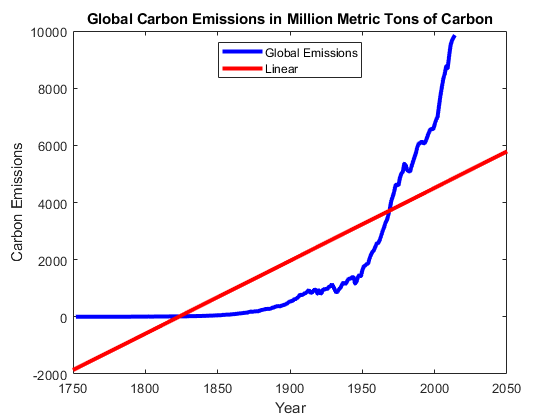


legend([emissions,best_line],{'Global Emissions','Linear'},'Location','north')


figure()
carbon = carbon_emissions_data(:,2); % carbon emissions data (column 2)
L = log(carbon); % natural logarithm of global carbon emissions
l_plot=plot(time,L,'-b','LineWidth',3)

l_plot =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×263 double]
              YData: [1×263 double]
              ZData: [1×0 double]

  Show all properties




title('Logarithm of Global Carbon Emissions')
xlabel('Year')
ylabel('Natural Logarithm of Carbon Emissions')

hold on

shift = mean(time) % exact mean of the time data

shift = 1883


D = [ones(size(time)) (time - shift) (time - shift).^2]; 

D2 = transpose(D) * D;

b=inv(D2)*transpose(D)*L

b =     5.3296
    0.0347
   -0.0000



y1 = @ (t) b(1) + b(2) * (t - shift);

best_line = plot([1750, 2050], y1([1750, 2050]), 'r', 'LineWidth', 3)

best_line =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1750 2050]
              YData: [0.7202 11.1173]
              ZData: [1×0 double]

  Show all properties


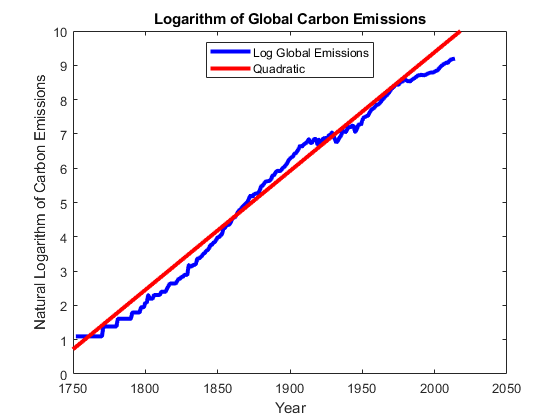


axis([1750 2050 0 10])

legend([l_plot,best_line],{'Log Global Emissions','Quadratic'},'Location','north')


clear, clc
filename = 'carbon_dioxide_data.mat'; % Data for the Keeling curve
load(filename)


time = carbon_dioxide_data(:,3); % Date/time in decimal years.
CO2 = carbon_dioxide_data(:,5); % CO2 data
CO2_trend = carbon_dioxide_data(:,6); % CO2 data trend

fig = figure(6);
subplot(2, 1, 1) 

Cs=plot(time,CO2,'cyan')

Cs =   Line with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×743 double]
              YData: [1×743 double]
              ZData: [1×0 double]

  Show all properties



hold on

CO2_T=plot(time,CO2_trend,'b')

CO2_T =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×743 double]
              YData: [1×743 double]
              ZData: [1×0 double]

  Show all properties


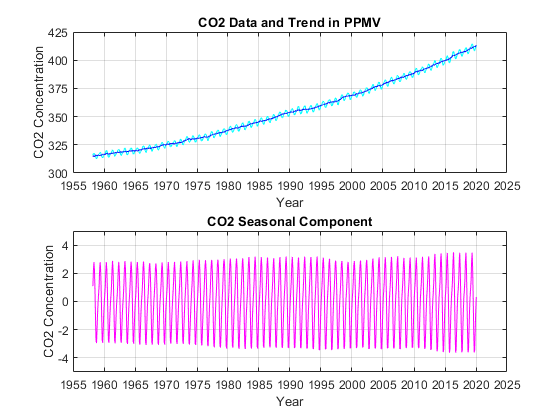



title('CO2 Data and Trend in PPMV')
xlabel('Year')
ylabel('CO2 Concentration')

grid on
set(gca,'FontSize',9)
axis([1955 2025 300 425])
xticks(1955:5:2025)
yticks(300:25:425)

subplot(2, 1, 2) 

plot(time,(CO2 - CO2_trend),'magenta')
title('CO2 Seasonal Component')
xlabel('Year')
ylabel('CO2 Concentration')

grid on
axis([1955 2025 -5 5])

xticks(1955:5:2025)
yticks(-4:2:4)


n = numel(time)

n = 743

subplot(2,1,1) % add the best-line to the top tile.
shift = mean(time) % numerical mean of the time data

shift = 1.9891e+03

D = [ones(size(time)) (time - shift)]; % allows to shift time series to the mean
D2 = transpose(D) * D

D2 = 	1.0e+05 *

    0.0074         0
         0    2.3737



y=CO2_trend;

b=inv(D2)*transpose(D)*y

b =   354.8731
    1.5703


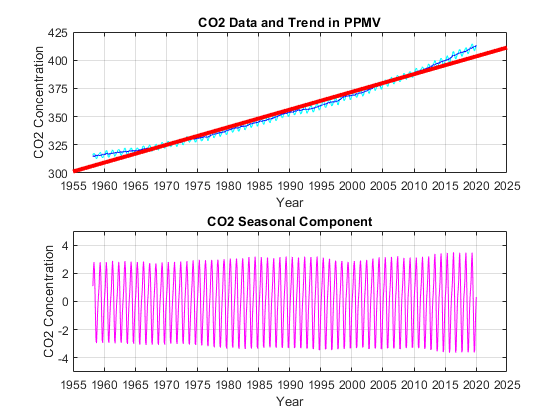

best_line =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1955 2025]
              YData: [301.2866 411.2075]
              ZData: [1×0 double]

  Show all properties



y1 = @(t) b(1) + b(2) * (t - shift);


best_line = plot([1955, 2025], y1([1955, 2025]), 'r', 'LineWidth', 3)



D = [ones(size(time)) (time - shift) (time-shift).^2]; 
D2 = transpose(D) * D

D2 = 	1.0e+08 *

    0.0000         0    0.0024
         0    0.0024   -0.0000
    0.0024   -0.0000    1.3650



y=CO2_trend;

b=inv(D2)*transpose(D)*y

b =   350.7689
    1.5703
    0.0128


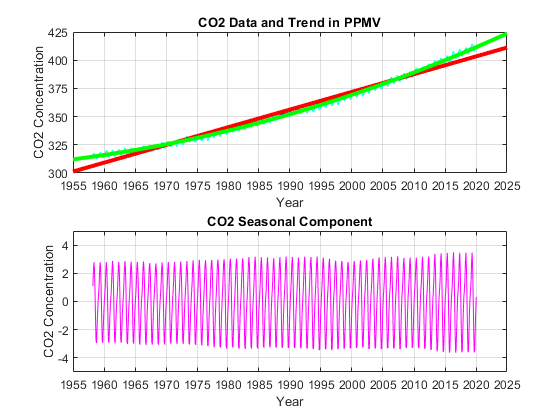

Quadratic =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×71 double]
              YData: [1×71 double]
              ZData: [1×0 double]

  Show all properties


y2 = @(t) b(1) + b(2) * (t - shift) + b(3) * (t - shift).^2;


Quadratic = plot([1955:1:2025], y2([1955:1:2025]), 'g', 'LineWidth', 3)



D = [ones(size(time)) (time - shift) (time-shift).^2 (time-shift).^3];

D2 = transpose(D) * D

D2 = 	1.0e+10 *

    0.0000         0    0.0000         0
         0    0.0000   -0.0000    0.0136
    0.0000   -0.0000    0.0136   -0.0000
         0    0.0136   -0.0000    9.3444



y=CO2_trend;

b=inv(D2)*transpose(D)*y

b =   350.7689
    1.5554
    0.0128
    0.0000



y3 = @(t) b(1) + b(2) * (t - shift) + b(3) * (t - shift).^2 + b(4) * (t - shift).^3;

Cubic = plot([1955:1:2025], y3([1955:1:2025]), '--k', 'LineWidth', 3)

Cubic =   Line with properties:

              Color: [0 0 0]
          LineStyle: '--'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×71 double]
              YData: [1×71 double]
              ZData: [1×0 double]

  Show all properties


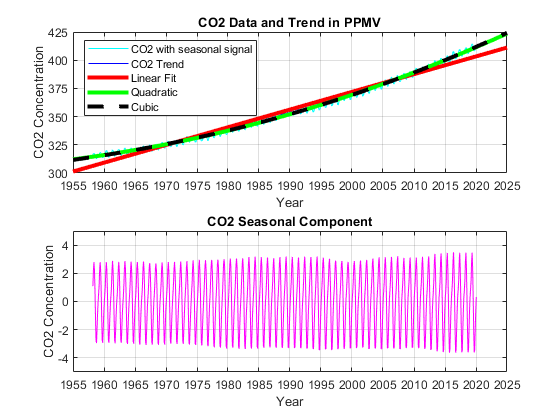


legend([Cs,CO2_T,best_line,Quadratic,Cubic],{'CO2 with seasonal signal','CO2 Trend','Linear Fit','Quadratic','Cubic'},'Location','northwest')